# Karakteristika

Fs = 0.2;
Ts = 1/Fs;
T = 300;
t = 0:Ts:T;
N = length(t);
F = 1 / (N * T);
fmax = 1/(2*T);
v = 0:F:(fmax - F); %frequency vector
u = ones(1,(T*Fs)+1);
simin = [t',u'];

% open_system("seminar_simulink")
simy = [];
for i = 0:0.1:2.5
    u = ones(1,(T*Fs)+1)*i;
    simin = [t',u'];
    set_param('seminar_simulink','StopTime',int2str(T));
    sim("seminar_simulink");
    simy = [ans.simouty.Data,simy];
end

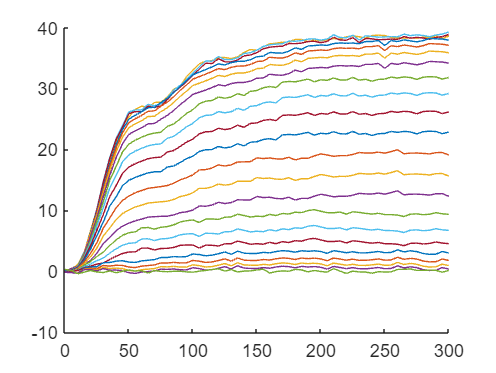

figure;
hold on;
for i = 1:length(simy(1,:))
    plot(t',simy(:,i));
end

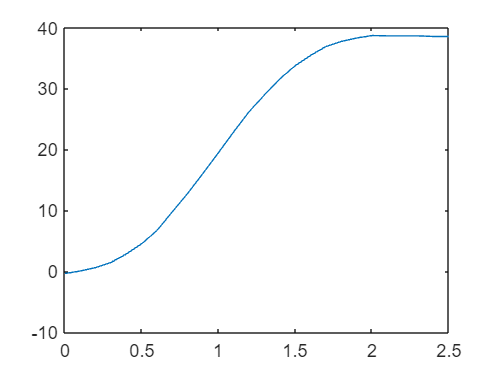

const = [];
for i = 1:length(simy(1,:))
    const = [mean(simy(end-20:end,i)),const];
end
figure
plot(0:0.1:2.5,const)

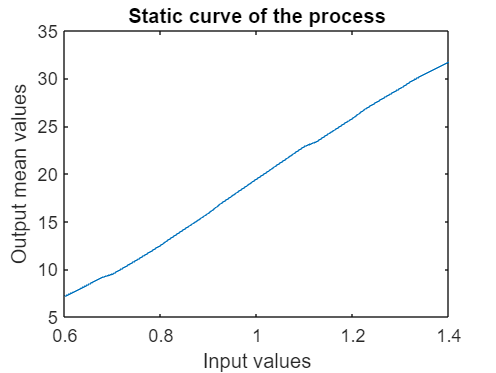

% open_system("seminar_simulink")
simy_short = [];
for i = 0.6:0.025:1.4
    u = ones(1,(T*Fs)+1)*i;
    simin = [t',u'];
    set_param('seminar_simulink','StopTime',int2str(T));
    sim("seminar_simulink");
    simy_short = [ans.simouty.Data,simy_short];
end
const_short = [];
for i = 1:length(simy_short(1,:))
    const_short = [mean(simy_short(end-20:end,i)),const_short];
end
figure
plot(0.6:0.025:1.4,const_short)
xlabel("Input values")
ylabel("Output mean values")
title("Static curve of the process")

## Frekvenčni Odziv

Fs = 0.0625;
Ts = 1/Fs;
T = 19200;
t = 0:Ts:T;
N = length(t);
F = 1 / (N * T);
fmax = 1/(2*T);
v = 0:F:(fmax - F); %frequency vector
u = ones(1,(T*Fs)+1);
simin = [t',u'];

U_PRBS = 0.6 + prbs(10)*0.8;
U_const = ones(length(t)-length(U_PRBS),1);
simin_PRBS = [U_const;U_PRBS];
simin = [t',simin_PRBS];
% open_system("seminar_simulink");
set_param('seminar_simulink','StopTime',int2str(T));
sim("seminar_simulink");
simy_PRBS = [simin,ans.simouty.Data];

t = simy_PRBS(1:end-178,1);
u = simy_PRBS(179:end,2)-1;
y = simy_PRBS(179:end,3)-19.1;

t = simy_PRBS(:,1);
u = simy_PRBS(:,2)-1;
y = simy_PRBS(:,3)-19.1;

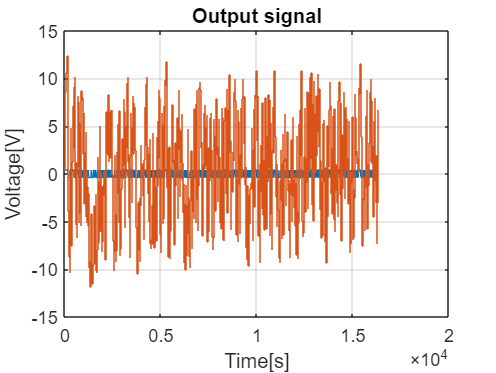

figure
plot(t,u)
hold on
stairs(t,y)
xlabel('Time[s]');
ylabel('Voltage[V]');
title('Output signal');
grid on;

N = length(t);
T = t(2,1) - t(1,1);
F = 1 / (N * T);
fmax = 1/(2*T);
v = 0:F:(fmax - F+F); %frequency vector

## FFT

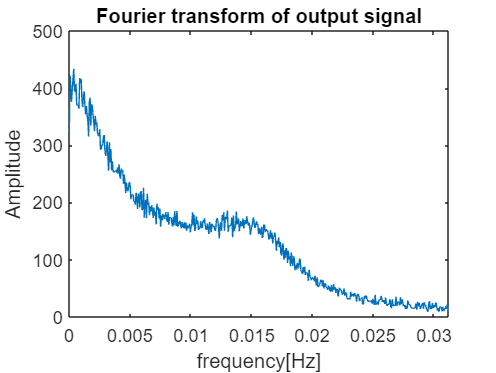

FT_input = fft(u);
FT_output = fft(y);

figure;
plot(v,abs(FT_output(1:(end+1)/2)))
title("Fourier transform of output signal")
xlabel("frequency[Hz]")
ylabel("Amplitude")

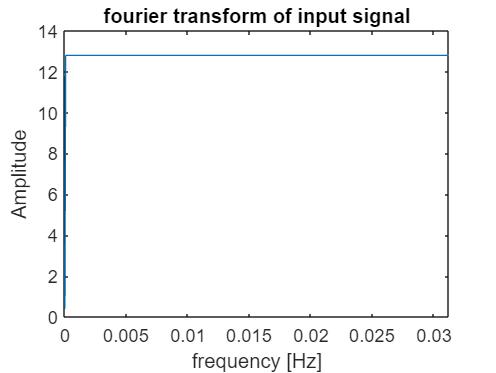


plot(v,abs(FT_input(1:(end+1)/2)))
title("fourier transform of input signal")
xlabel("frequency [Hz]")
ylabel("Amplitude")

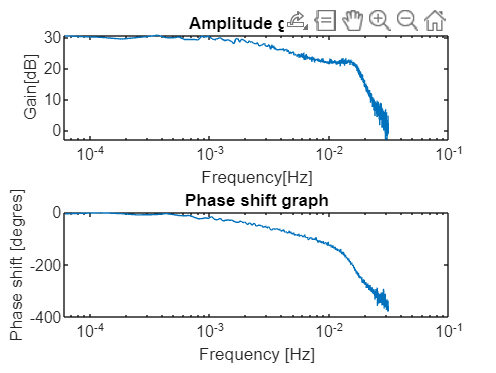

G_jw = FT_output ./ FT_input;
faza = unwrap(angle(G_jw));

subplot(2,1,1), semilogx(v,20*log10(abs(G_jw(1:(end+1)/2))))
title("Amplitude graph")
xlabel("Frequency[Hz]")
ylabel("Gain[dB]")
subplot(2,1,2), semilogx(v,180/pi*(faza(1:(end+1)/2)))
title("Phase shift graph")
xlabel("Frequency [Hz]")
ylabel("Phase shift [degres]")

n = 3;
d = 0;
N = length(y);
num_columns = 1 + n + d;
num_rows = N - n - d; 
k = d + n + 1;
psi = [];

for i = 1:n
    psi = [psi, -y(k-i:N-i)];
end

for i = 1:n
    psi =[psi,u(k-d-i:N-d-i)];
end

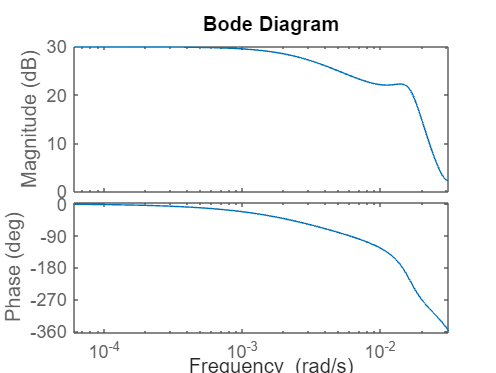


y_short = y((n+d+1):end);
Th = psi \ y_short;
T = T*2*pi;
numerator = Th(n+1:(n*2));
denominator = [1; Th(1:n)];
G = tf(numerator', denominator', T);
G.inputdelay = d;


N = length(t);
T = t(2,1) - t(1,1);
F = 1 / (N * T);
fmax = 1/(2*T);
v = 0:F:(fmax - F + F); %frequency vector

figure
bode(G,v);

[MAG, PH]=bode(G, v);
MAG = MAG(:);
PH = PH(:);
FT_input = fft(u);
FT_output = fft(y);

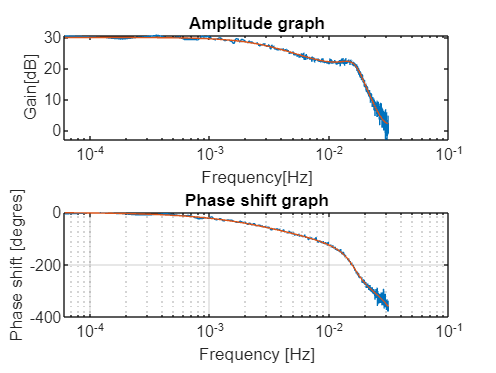

% G_jw = FT_output ./ FT_input;
% faza = unwrap(angle(G_jw));
figure

subplot(2,1,1), semilogx(v,20*log10(abs(G_jw(1:(end+1)/2))))
hold on
subplot(2,1,1), semilogx(v,20*log10(MAG))
title("Amplitude graph")
xlabel("Frequency[Hz]")
ylabel("Gain[dB]")

subplot(2,1,2), semilogx(v,180/pi*(faza(1:(end+1)/2)))
hold on
subplot(2,1,2), semilogx(v,PH)
grid
title("Phase shift graph")
xlabel("Frequency [Hz]")
ylabel("Phase shift [degres]")